# Solution to the *Clustering Wine Quality *exercise

## 1. Load data

Load the data in `wineQuality.mat`.

load wineQuality

This file contains a table, `data`, with 13 variables, containing chemical composition data for about 6,500 wines, as well as a quality rating and the color of the wine (red or white). The numeric data (the chemical measurements and the quality rating) is also stored in the matrix `numdata`. 

## 2. Perform PCA

Use PCA to transform the numeric data. Visualize the importance of the components with a Pareto plot.

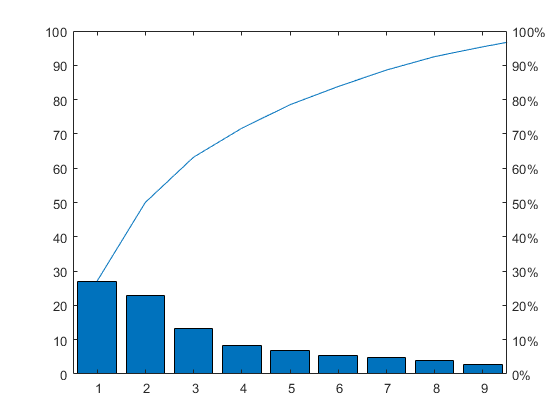

[~,scrs,~,~,pexp] = pca(numdata);
pareto(pexp)

## 3. Visualize the reduced data

Visualize the transformed data in two dimensions by making a scatter plot of the data in the first two components. Does it appear that there are distinct clusters?

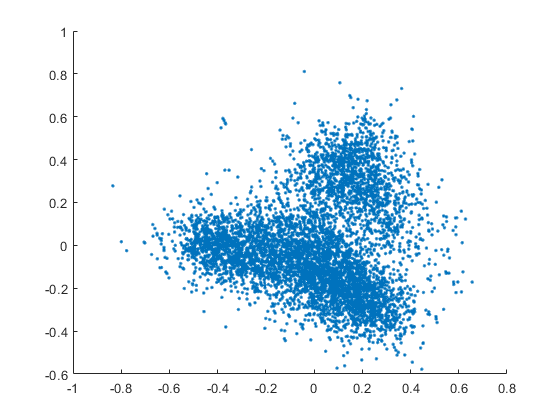

figure
scatter(scrs(:,1),scrs(:,2),'.')

## 4. Cluster into 2 groups

Cluster the data into two groups. Experiment with *k*-means and/or GMM clustering, making grouped scatter plots to ensure that the clustering divides the data as you would expect.

Set random seed for reproducibility.

rng(1234)

*k*-means

g = kmeans(numdata,2,'Replicates',5);

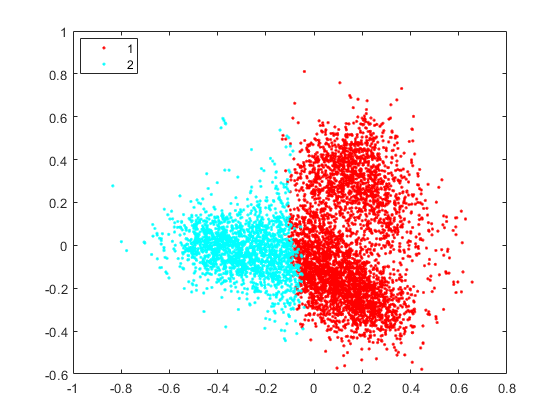

figure
gscatter(scrs(:,1),scrs(:,2),g,[],'.')

GMM

gmm = fitgmdist(numdata,2,'Replicates',5);

g = cluster(gmm,numdata);

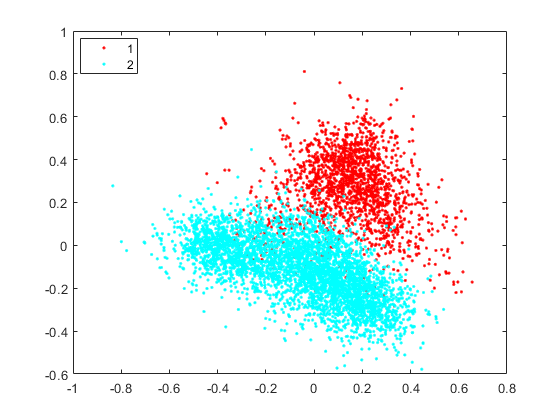

figure
gscatter(scrs(:,1),scrs(:,2),g,[],'.')

## 5. Cross-tabulate grouping and wine color

Compare the resulting clusters with the groups in the `Color` variable using `crosstab`.

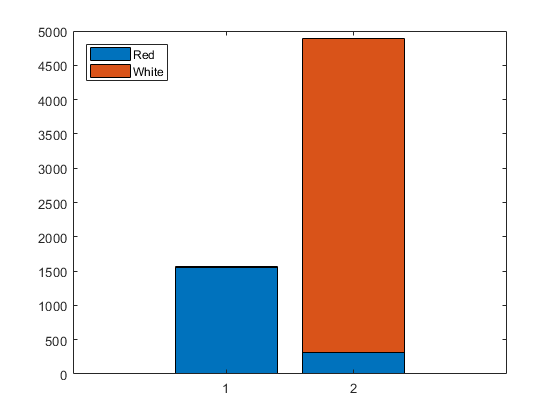

figure
bar(crosstab(data.Color,g),'stacked')
legend(categories(data.Color),'Location','northwest')